assert(endsWith(pwd, "non-ferromagnetic metal plate with hole in time domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

Coil.num = 2;
Coil.inner_radius = [3.75e-3 3.75e-3]; % (m)
Coil.outer_radius = [6.00e-3 6.00e-3]; % (m)
Coil.length       = [4.00e-3 4.00e-3]; % (m)

Coil.wire_diameter = [0.35e-3 0.35e-3]; % (m)
Coil.N_turns = [60 60];

Coil_pos = [-20e-3, 0, 4e-3
            6e-3, 0, 4e-3]; % (m)
Coil = SetPositionRotation3D(Coil, Coil_pos, repmat([1,0,0],Coil.num,1), repmat([0],Coil.num,1));
clear Coil_pos

#### Sensor

Sensor.num = 1;
Sensor.side_length = 1e-3;

Sensor_pos = [-20e-3, 0, 1.5e-3];
Sensor = SetPositionRotation3D(Sensor, Sensor_pos, [1,0,0], 0);
clear Sensor_pos

#### Model

vertex_file = 'plate_l72_t2_hole_d12_vertex.csv';
element_file = 'plate_l72_t2_hole_d12_element.csv';
Model = BuildModel3D('File', vertex_file, element_file, 1e-3);

build model took 0.06 seconds


clear vertex_file element_file

Model.conductivity = 7.407e5 * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation3D(Model, Coil);

build governing equation took 14.56 seconds


#### Solve in time domain

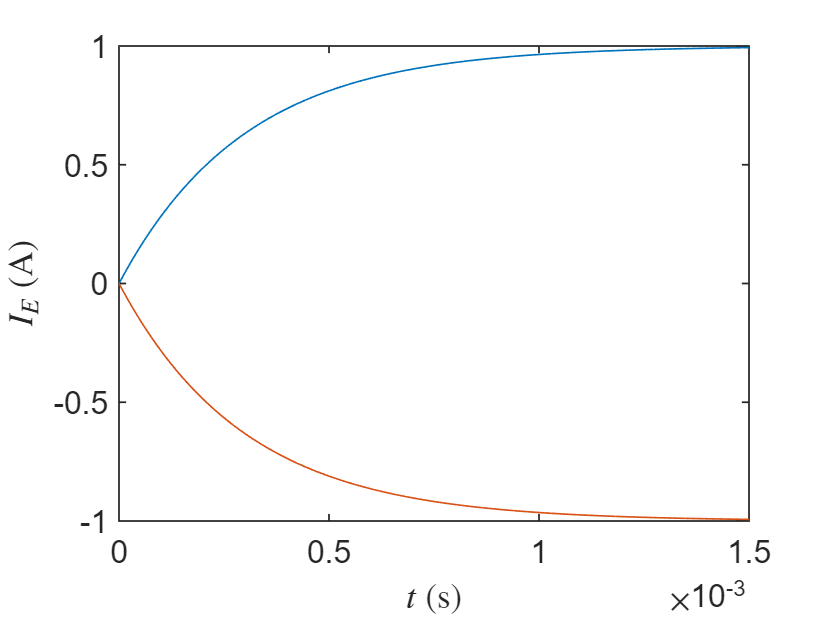

I_E_ss = [1 -1]; % (A)
tau = 3e-4; % (s)

Coil.time_domain.current      = @(t) I_E_ss .* (1 - exp(-t/tau));
Coil.time_domain.current_diff = @(t) I_E_ss/tau .* exp(-t/tau);
Coil.time_domain.time_span = [0, 1.5e-3]; % (s)

t = linspace(Coil.time_domain.time_span(1), Coil.time_domain.time_span(end))';
plot(t, Coil.time_domain.current(t))
ylabel('$I_E$ (A)', 'Interpreter','latex')
xlabel('$t$ (s)', 'Interpreter','latex')

clf
clear I_E_ss tau t

[Model, Coil, Sensor] = SolveTimeDomain3D(GoverningEquation, Model, Coil, Sensor);

solve current density took 27.78 seconds
solve magnetic flux density took 1.33 seconds


#### Plot result

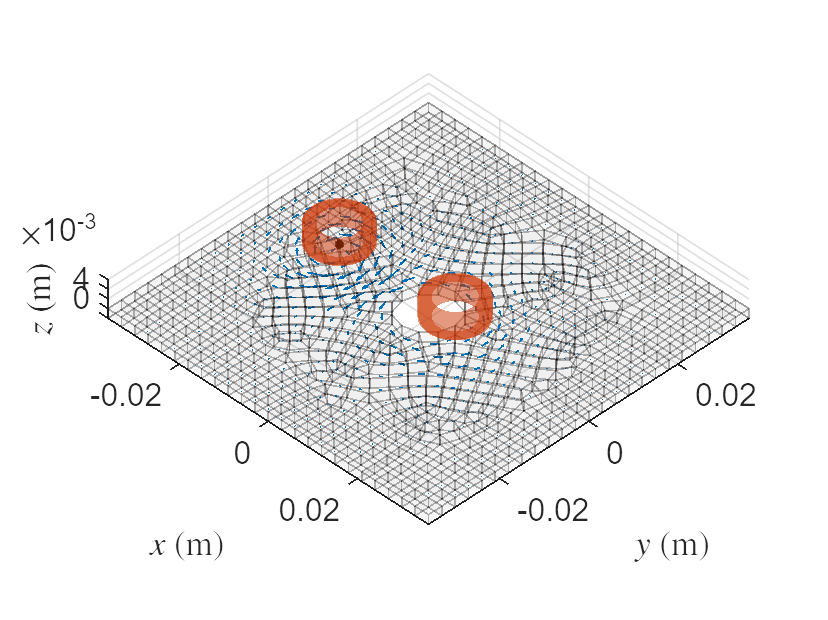

pos = Model.elms_center;
t = 0.3e-3; % (s)
[~,k] = min(abs(t - Model.time_domain.t));
vec = Model.time_domain.J(:,:,k);
quiver3(pos(1,:),pos(2,:),pos(3,:), vec(1,:),vec(2,:),vec(3,:));
clear t k pos vec

PlotWorld3D(Model, Coil, Sensor);

clf